**PREDICTING**

**Cases Model**

[cases_learning_data.YY, cases_learning_data.MM, cases_learning_data.DD] = ymd(cases_learning_data.datetime);
cases_learning_data = removevars(cases_learning_data, "datetime");

**Sample of the Cases Model Data**

Training a machine learning model is time-consuming, as such, only a small sample of the learning will be used to train the model. In this case, 5% of the data is randomly selected to train the model.

selectedRows = randi(height(cases_learning_data), round(height(cases_learning_data) * 0.05), 1);
casesDataSample = cases_learning_data(selectedRows, :);

**Training Data and Testing Data (cases)**

The sample data is split into training data and testing data. The training data is used to train the model, whereas, the testing model is used for validation - ensuring it does not overfit.

casesTrain = datasample(casesDataSample, round(height(casesDataSample) * 0.75));
casesValidation = setdiff(casesDataSample, casesTrain);

**Training the Cases Model / Loading in the Cases Model**

Fine tree regression model

load('casesModel.mat');
%casesModel = trainCasesModel(casesTrain);

**Cases Predictions**

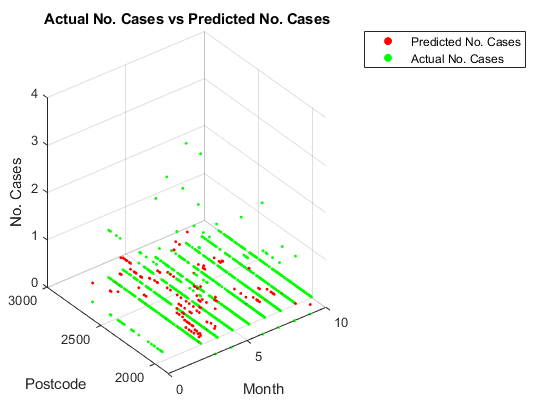

ypred = casesModel.predictFcn(casesValidation);
figure()
scatter3(casesValidation.MM, casesValidation.postcode, ypred, 5, "red", "filled")
hold on;
scatter3(casesValidation.MM, casesValidation.postcode, casesValidation.cases, 5, "green", "filled")
hold off;
title("Actual No. Cases vs Predicted No. Cases")
xlabel("Month")
ylabel("Postcode")
zlabel("No. Cases")
legend("Predicted No. Cases", "Actual No. Cases")

**Tests Model**

[tests_learning_data.YY, tests_learning_data.MM, tests_learning_data.DD] = ymd(tests_learning_data.datetime);
tests_learning_data = removevars(tests_learning_data, "datetime");

**Sample of the Tests Model Data**

Training a machine learning model is time-consuming, as such, only a small sample of the learning will be used to train the model. In this case, 5% of the data is randomly selected to train the model.

selectedRows = randi(height(tests_learning_data), round(height(tests_learning_data) * 0.05), 1);
testsDataSample = tests_learning_data(selectedRows, :);

**Training Data and Testing Data (tests)**

The sample data is split into training data and testing data. The training data is used to train the model, whereas, the testing model is used for validation - ensuring it does not overfit.

testsTrain = datasample(testsDataSample, round(height(testsDataSample) * 0.75));
testsValidation = setdiff(testsDataSample, testsTrain);

**Training the Cases Model / Loading in the Cases Model**

Fine tree regression model

load('testsModel.mat');
%casesModel = traintestsModel(casesTrain);

**Tests Predictions**

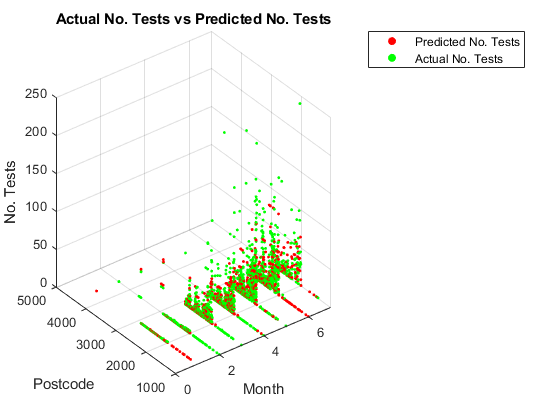

ypred = testsModel.predictFcn(testsValidation);
figure()
scatter3(testsValidation.MM, testsValidation.postcode, ypred, 5, "red", "filled")
hold on;
scatter3(testsValidation.MM, testsValidation.postcode, testsValidation.tests, 5, "green", "filled")
hold off;
title("Actual No. Tests vs Predicted No. Tests")
xlabel("Month")
ylabel("Postcode")
zlabel("No. Tests")
legend("Predicted No. Tests", "Actual No. Tests")

Deletes variables (that are not needed)

clear selectedRows;